# cargar_datos_xsens

Read a text file generated by the xsens. The format of these data is the calibrated output format, which consists of 10 measurements in each sampling period:

## Syntax

`[medicion]= cargar_datos_xsens(file,idname)`  

## Description

`[medicion]= cargar_datos_xsens(file,idname)` `file` is the name of the file, and `idname` an identifier of the data structure where the data will be stored. 

The data structure that the function creates has the form:

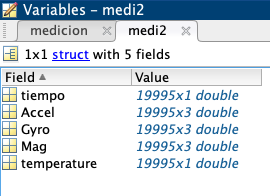 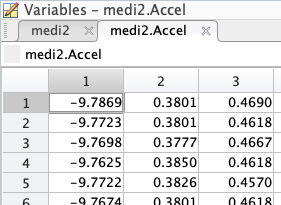

The work units are those corresponding to the international measurement system: m/s^2 for accelerations, rad/s for angular velocities, and u.a. (arbitrary units without real physical sense) for the measurement of the magnetic field. All toolbox functions expect to work with these units, and produce their results in units of the international system.

## Examples

% Lectura de un archivo:
[medi2] = cargar_datos_xsens('xsens_686aa.txt','sensorCOG')

medi2 = struct with fields:
         tiempo: [19995×1 double]
          Accel: [19995×3 double]
           Gyro: [19995×3 double]
            Mag: [19995×3 double]
    temperature: [19995×1 double]


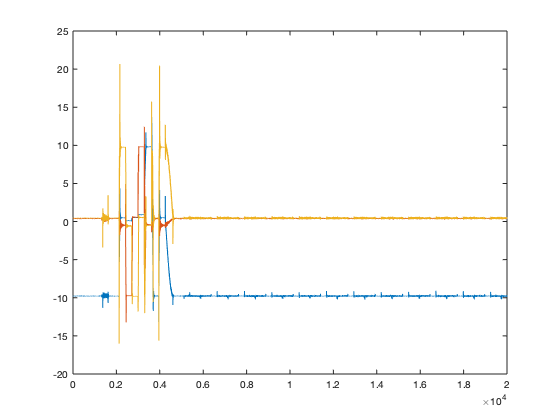


% Representa loa acelerometros:
plot(medi2.Accel)

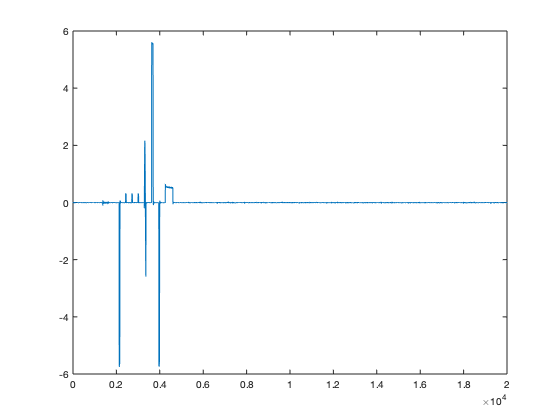

% El giroscopio en Y:
plot(medi2.Gyro(:,2))